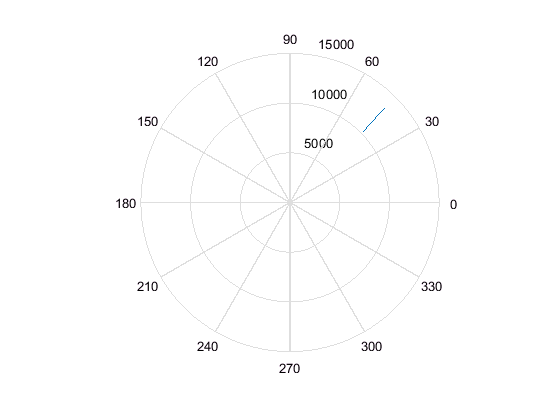

clc; clear all; close all

n=26;
t=2;
sigmaD=30;
sigmaB=0.09;
X(2,n)=zeros();
V(2,n)=zeros();
x0=13500/sqrt(2);
y0=13500/sqrt(2);
X(:,1)=[x0;y0];
V(:,1)=[-50;-45];
ErrSumextrD=0;
ErrSumfiltrD=0;
ErrSumextrB=0;
ErrSumfiltrB=0;

for i=2:n
    X(:,i)=X(:,i-1)+V(:,i-1)*t;
    V(:,i)=V(:,i-1);
end

for i=1:n
    D(i)=sqrt(X(1,i)^2+X(2,i)^2);
    B(i)=atan(X(1,i)/X(2,i));
end

polar(B,D); %point 2

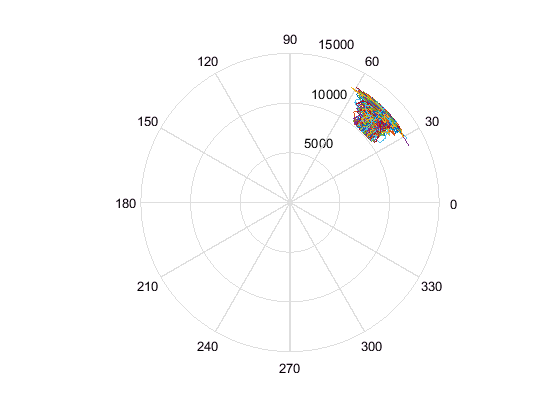



%for M=500 times
M=500;
for i=1:M
    etaB = normrnd(0,sigmaB,1,n);
    etaD = normrnd(0,sigmaD,1,n);
    Dm=D+etaD;
    Bm=B+etaB;
    for i=1:26;
        Xm(i)=Dm(i)*sin(Bm(i));
        Ym(i)=Dm(i)*cos(Bm(i));
    end
    
    for i=1:26
        Zc(1,i)=Xm(i);
        Zc(2,i)=Ym(i);
    end
    %polar(Bm,Dm);
    %F, G, H, P
    sigmaA=0;
    F=[1 t 0 0;
        0 1 0 0;
        0 0 1 t;
        0 0 0 1];
    H=[1 0 0 0;
        0 0 1 0];
    G=0;
    P=(10^10)*eye(4);
    
    bias=0;
    
    
    [ Xk,Dmextr,Dmfiltr,Bmextr,Bmfiltr, R] = calcKalman4(Zc, sigmaA, sigmaD, sigmaB, Dm, Bm, F, G, H, P, bias );
    
    Dk=(Xk(1,:).^2+Xk(3,:).^2).^0.5;
    Bk=atan(Xk(1,:)./Xk(3,:));
    
    ErrCurextrD = ( Dmextr - D).^2;
    ErrCurfiltrD = (Dmfiltr - D).^2;
    ErrCurextrB = ( Bmextr - B).^2;
    ErrCurfiltrB = (Bmfiltr - B).^2;
    
    
    ErrSumextrD = ErrSumextrD +  ErrCurextrD;
    ErrSumfiltrD = ErrSumfiltrD +  ErrCurfiltrD;
    ErrSumextrB = ErrSumextrB +  ErrCurextrB;
    ErrSumfiltrB = ErrSumfiltrB +  ErrCurfiltrB;
    
    polar(Bk(2:end),Dk(2:end));
    hold on
    polar(B,D)
    % figure
    % hold on
    % plot(D)
    % plot(Dk)
    % figure
    % hold on
    % plot(B)
    % plot(Bk)
    
end

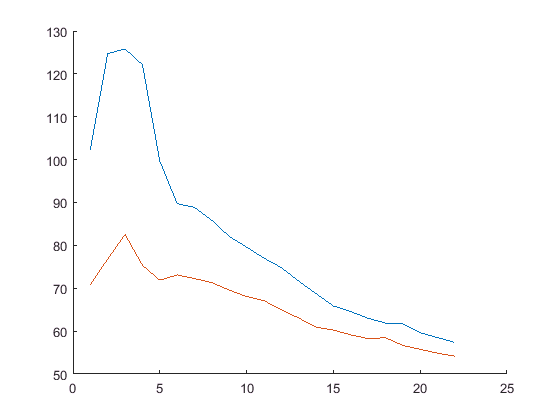

FinalErrorextrD = (  ErrSumextrD(3:end)./(M-1) ).^0.5;
FinalErrorfiltrD = (  ErrSumfiltrD(3:end)./(M-1) ).^0.5;
FinalErrorextrB = (  ErrSumextrB(3:end)./(M-1) ).^0.5;
FinalErrorfiltrB = (  ErrSumfiltrB(3:end)./(M-1) ).^0.5;

 figure
 hold on
plot(FinalErrorextrD(3:end))
plot(FinalErrorfiltrD(3:end))

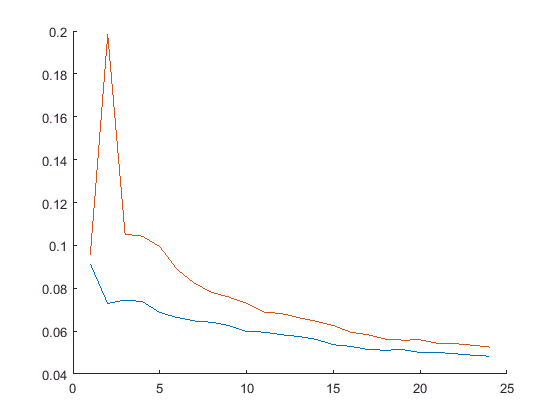

figure
hold on
plot(FinalErrorfiltrB)
plot(FinalErrorextrB)

% hold on
% polar(B,D);

% polar(Bmextr,Dmextr);
% polar(Bmfiltr,Dmfiltr);
